# Datasets y visualización

## Importar con readtable y readmatrix

%Readmatrix
area_mm=readmatrix("../../Clase Github/Utils4SP/Datasets/areaMM.txt","Delimiter","   ")

area_mm =   340.4277  324.3750  308.9114  293.6813  277.8073  261.0772  245.9019  232.8705  218.6999  203.1390  189.3382  176.6128  169.5532  168.8775  172.0049  174.4247  178.4295  183.9891  193.8382  206.2434  219.7135  234.3422  248.6808  263.1539  276.9246  293.0711  308.6514  324.5290  339.1647  348.7149  354.1932  356.6855  356.3495  354.7398  355.8347  358.5429  363.1208  370.1026  377.4434  387.1900  396.7827  403.9608  411.5069  420.4716  429.3214  439.3651  448.8747  459.0157  469.0630  478.9387



%readtable
PSD_bands=readtable("../../Clase Github/Utils4SP/Datasets/2021.10.04_IntensidadBobinas.xlsx")

PSD_bands = 630×13 table
    Dist_cm_    PSD_B1      PSD_B2        PSD_B3       PSD_B4       PSD_B5      PSD_B6      PSD_B7       PSD_B8       PSD_B9       PSD_B10      PSD_B11     PSD_Base 
    ________    _______    _________    __________    _________    _________    _______    _________    _________    _________    _________    _________    _________

      0.5       0.54799     0.012948     0.0051533    0.0046358     0.020502     1.1388     0.010652    0.0029874    0.0060306    0.0044177    0.0027482     0.008748
      0.5       0.50418    0.00171

## Function custom de Import File

%Pasa sonda Cassini
Cassini=importfile_cassini("G:\Clase Github\Utils4SP\Datasets\05358_mrdcd_sdfgmc_krtp_1s.asc");

## Importar audio

[y,fs]=audioread("G:\Clase Github\Utils4SP\Datasets\Owl.wav");
%Escuchar
sound(y,fs)

## Datastore

%Le indicamos que una carpeta es un datastore
ds=datastore("../../Clase Github/Utils4SP/Datasets/AtmosferaLogger/");
ds.VariableNames=["Fecha" "Hora" "Pres_kpa" "Temp_C" "Hum_perc"];
ds.TextscanFormats=["%s" "%s" "%f" "%f" "%f"];

%Leer todas las entradas
atmosfera=readall(ds);

## Reordenando

%Solo si importa fecha y hora en dos columnas
atmosfera.DateTime=string(atmosfera.Fecha)+" "+string(atmosfera.Hora);
%Pasar de texto a fecha-hora
atmosfera.DateTime=datetime(atmosfera.DateTime,"Format","yyyyMMdd HH:mm:ss");
%Parche por si la tabla ya se importó
%atmosfera.Properties.VariableNames=["Fecha" "Hora" "Pres_kpa" "Temp_C" "Hum_perc" "Bat_V"];

## Limpieza

Tomaremos los datos entre el 18-May y el 26 de mayo a las 6am

%Puntos inicial y final en el tiempo
T1=datetime(2021,5,18,6,0,0)

T1 = datetime
   18-May-2021 06:00:00


T2=datetime(2021,5,26,6,0,0)

T2 = datetime
   26-May-2021 06:00:00



%Creando criterios de selección de datos
index= atmosfera.DateTime>T1 &...
    atmosfera.DateTime<T2;

atmosfera_part=atmosfera(index,:);

## Ploteo exploratorio

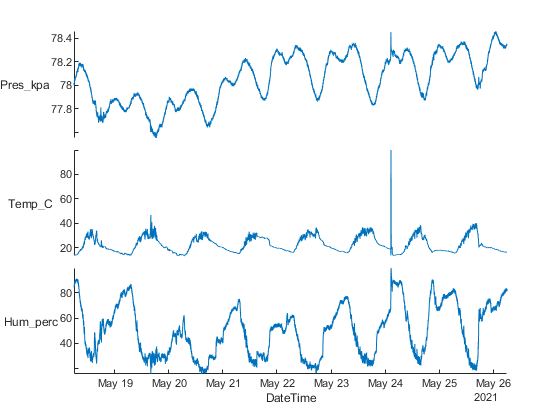

figure
stackedplot(atmosfera_part,"XVariable","DateTime")

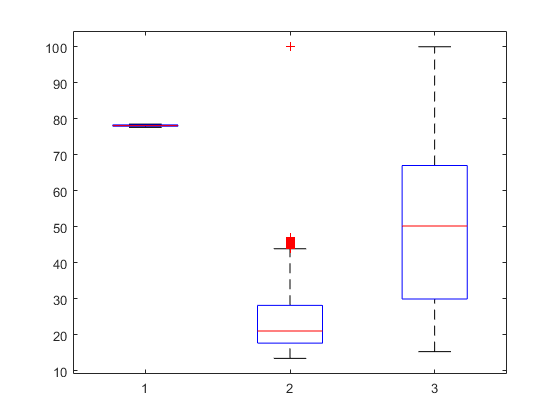


figure
boxplot(atmosfera_part{:,["Pres_kpa" "Temp_C" "Hum_perc"]})

## Histograma

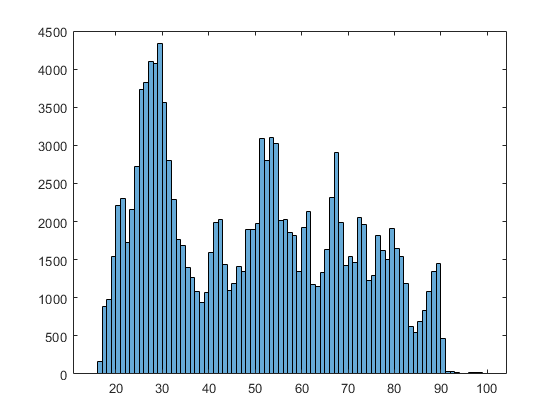

figure
histogram(atmosfera_part.Hum_perc)

figure
histogram(atmosfera_part.Hum_perc,"BinWidth",1)

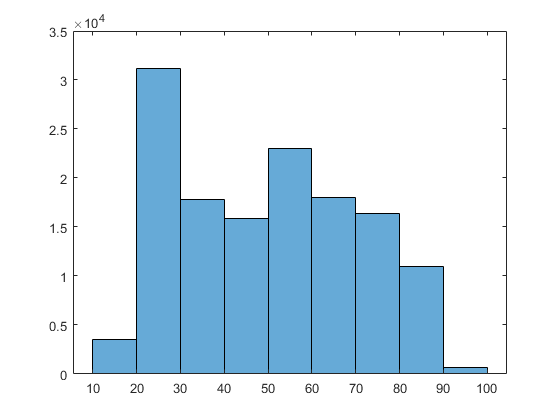

figure
histogram(atmosfera_part.Hum_perc,"BinWidth",10)

## Dispersión

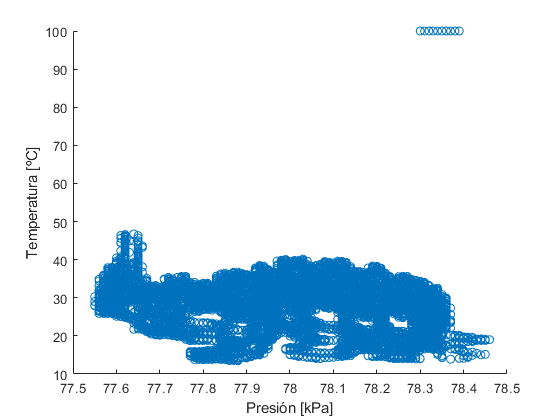

scatter(atmosfera_part.Pres_kpa,atmosfera_part.Temp_C)
xlabel("Presión [kPa]")
ylabel("Temperatura [ºC]")

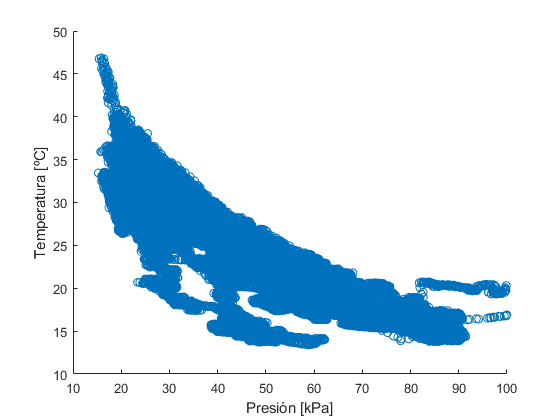

scatter(atmosfera_part.Hum_perc,atmosfera_part.Temp_C)
xlabel("Presión [kPa]")
ylabel("Temperatura [ºC]")

## Plot Matrix

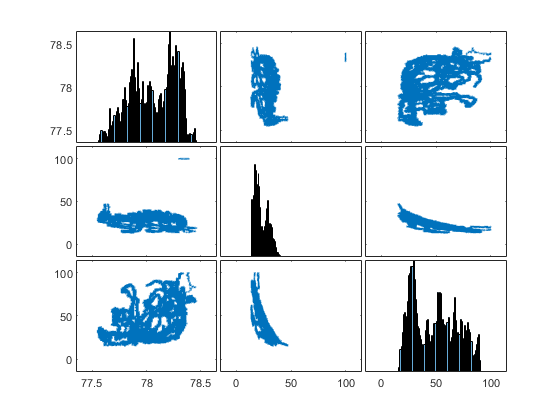

figure
plotmatrix(atmosfera_part{:,["Pres_kpa" "Temp_C" "Hum_perc"]})

## Tiledlayout

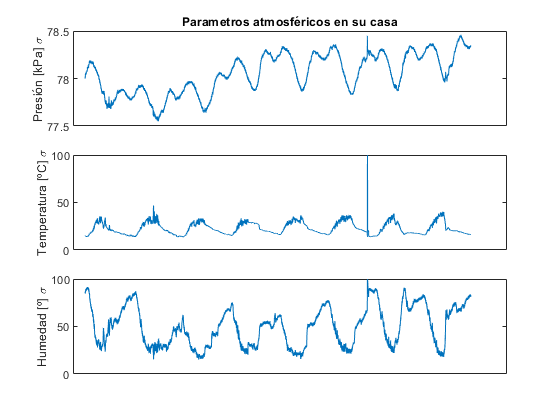

tiledlayout(3,1)
nexttile
plot(atmosfera_part.DateTime,atmosfera_part.Pres_kpa)
ylabel("Presión [kPa] \sigma")
%xlabel("Fecha")
title("Parametros atmosféricos en su casa")
set(gca,"xtick",[])

nexttile
plot(atmosfera_part.DateTime,atmosfera_part.Temp_C)
ylabel("Temperatura [ºC] \sigma")
%xlabel("Fecha")
set(gca,"xtick",[])

nexttile
plot(atmosfera_part.DateTime,atmosfera_part.Hum_perc)
ylabel("Humedad [º] \sigma")
%xlabel("Fecha")
set(gca,"xtick",[])